MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

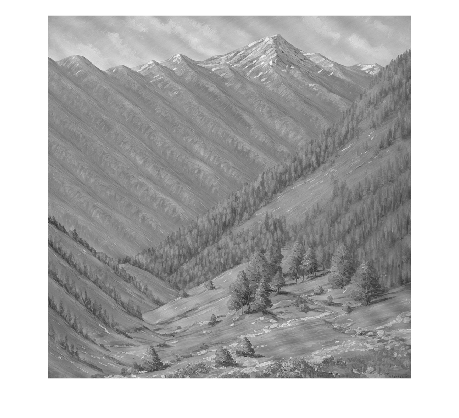

img = im2gray(imread(MAIN_DIR + "\part-1\filtered_image.png"));
imshow(img);

kernel = [0 -1 0; -1 5 -1; 0 -1 0];

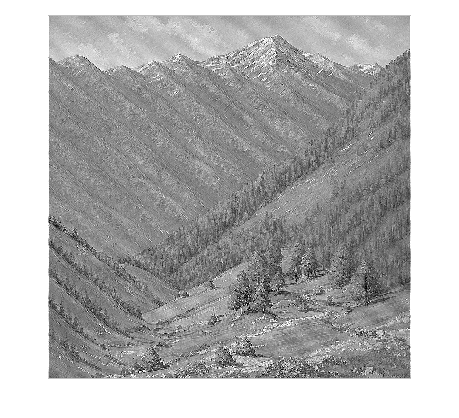

sharped_img_conv2d = cast(conv2(img, kernel), "uint8");
sharped_img_manual = cast(conv_pad(img, kernel),"uint8");
imshow(sharped_img_conv2d);

imwrite(sharped_img_conv2d, MAIN_DIR + "sharped_img_conv2_2times.png");
imshow(sharped_img_manual);

imwrite(sharped_img_manual, MAIN_DIR + "sharped_img_manual.png");

function y = conv_pad(img, kernel)
    h = height(img);
    w = width(img);
    fourier_transform_img = fftshift(fft2(img, h+height(kernel)-1,w+width(kernel)-1));
    fourier_transform_kernel = fftshift(fft2(kernel, h+height(kernel)-1,w+width(kernel)-1)); 
    fft_conv = fourier_transform_img.*fourier_transform_kernel;
    y = ifft2(ifftshift(fft_conv));
end